# Transmission Assignment

*Colton Layhue, RBE550, Spring 2023*

clc, clear, close all

## Environment Setup

show_model = true;

### Case

The thickness for all plates in the case is 25mm with the length, width, and height of the case being {280,210,300} mm. 

% case_length = 0.280; % mm
case_width = 0.420; % mm
% case_height = 0.600; % mm

base_offset = 0.025;
z_offset = 0.48;

#### Solid Front and Back Walls

solid_length = 0.610;
wall_thickness = 0.025;
solid_height = 0.600;

solid_back = collisionBox(solid_length, wall_thickness, solid_height);
solid_front = collisionBox(solid_length, wall_thickness, solid_height);

solid_front.Pose = trvec2tform([(-0.660/2)  - base_offset, wall_thickness/2, wall_thickness - z_offset + solid_height/2]);
solid_back.Pose = trvec2tform([(-0.660/2) - base_offset, case_width - wall_thickness/2, wall_thickness - z_offset + solid_height/2]);

if show_model
    % show(solid_front)
    % hold on
    show(solid_back)
    hold on
end

#### Front and Rear Walls



front1_height = 0.250-0.080;
front2_height = 0.230+ 0.160;
front3_height = 0.230+ 0.160;
front4_height = 0.650-0.23-0.25-0.08;
front5_height = 0.23-0.16;

% make front geometries
front1 = collisionBox(wall_thickness, 0.42, front1_height);
front2 = collisionBox(wall_thickness, 0.210-0.08, front2_height);
front3 = collisionBox(wall_thickness, 0.210-0.08, front3_height);
front4 = collisionBox(wall_thickness, 0.42, front4_height);
front5 = collisionBox(wall_thickness, 0.42-2*(0.210-0.08), front5_height);

% adjust front position
front1.Pose = trvec2tform([(-wall_thickness/2) - base_offset,0.42/2, (front1_height/2) - z_offset]);
front2.Pose = trvec2tform([(-wall_thickness/2) - base_offset,(0.210-0.08)/2, (front1_height + front2_height/2) - z_offset]);
front3.Pose = trvec2tform([(-wall_thickness/2) - base_offset,0.42-((0.210-0.08)/2), (front1_height + front2_height/2) - z_offset]);
front4.Pose = trvec2tform([(-wall_thickness/2) - base_offset,0.42/2, (front1_height + front2_height + front4_height/2) - z_offset]);
front5.Pose = trvec2tform([(-wall_thickness/2) - base_offset,0.42/2, (front1_height + front2_height/2) - z_offset]);

% make rear geometries
rear1 = collisionBox(wall_thickness, 0.42, front1_height);
rear2 = collisionBox(wall_thickness, 0.210-0.08, front2_height);
rear3 = collisionBox(wall_thickness, 0.210-0.08, front3_height);
rear4 = collisionBox(wall_thickness, 0.42, front4_height);
rear5 = collisionBox(wall_thickness, 0.42-2*(0.210-0.08), front5_height);

% adjust rear position
rear1.Pose = trvec2tform([-1*(wall_thickness  + solid_length + base_offset),0.42/2, (front1_height/2) - z_offset]);
rear2.Pose = trvec2tform([-1*(wall_thickness + solid_length + base_offset),(0.210-0.08)/2, front1_height + (front2_height/2) - z_offset]);
rear3.Pose = trvec2tform([-1*(wall_thickness  + solid_length + base_offset),0.42-((0.210-0.08)/2), front1_height + (front2_height/2)- z_offset]);
rear4.Pose = trvec2tform([-1*(wall_thickness  + solid_length + base_offset),0.42/2, front1_height + front2_height + (front4_height/2)- z_offset]);
rear5.Pose = trvec2tform([-1*(wall_thickness + solid_length + base_offset),0.42/2, front1_height + (front2_height/2) - z_offset]);

if show_model
    show(front1)
    xlim([-0.98 0.15])
    ylim([-0.60 0.54])
    zlim([-0.6 0.8])
    view([-11.33 12.12])

    % hold on
    show(front2)
    show(front3)
    show(front4)
    show(front5)
    % hold off
    % 
    show(rear1)
    % % hold on
    show(rear2)
    show(rear3)
    show(rear4)
    show(rear5)
    % hold off
end

#### Solid Top and Bottom Walls

% top = collisionBox(0.610, 0.420, 0.025);
bottom = collisionBox(0.610, 0.420, 0.025);

% top.Pose = trvec2tform([-0.330 - base_offset, 0.210, 0.650-(wall_thickness/2)- z_offset]);
bottom.Pose = trvec2tform([-0.330 - base_offset, 0.210, (wall_thickness/2) - z_offset]);

if show_model
%     show(top)
    show(bottom)
    % hold off
end



### Countershaft

Gears are denoted as cylinders from left to right

cs_1 = collisionCylinder(0.072/2, 0.660);
cs_2 = collisionCylinder(0.2/2, 0.05);
cs_3 = collisionCylinder(0.16/2, 0.05);
cs_4 = collisionCylinder(0.247/2, 0.084);
cs_5 = collisionCylinder(0.279/2, 0.05);
cs_6 = collisionCylinder(0.280/2, 0.05);

cs_1.Pose = trvec2tform([-0.330 - base_offset, 0.210, 0.250- z_offset])*axang2tform([0 1 0 pi/2]);
cs_2.Pose = trvec2tform([-1*(0.076+.025 + base_offset), 0.210, 0.250- z_offset])*axang2tform([0 1 0 pi/2]);
cs_3.Pose = trvec2tform([-1*(0.076+0.05+0.076+.025 + base_offset), 0.210, 0.250- z_offset])*axang2tform([0 1 0 pi/2]);
cs_4.Pose = trvec2tform([-1*(0.318+0.025 + base_offset), 0.210, 0.250- z_offset])*axang2tform([0 1 0 pi/2]);
cs_5.Pose = trvec2tform([-1*(0.402+0.025 + base_offset), 0.210, 0.250- z_offset])*axang2tform([0 1 0 pi/2]);
cs_6.Pose = trvec2tform([-1*(0.660-.06-0.025 + base_offset), 0.210, 0.250- z_offset])*axang2tform([0 1 0 pi/2]);

if show_model
    show(cs_1)
    show(cs_2)
    show(cs_3)
    show(cs_4)
    show(cs_5)
    show(cs_6)
%     hold off
end

### Mainshaft

Right end of mainshaft will be modeled as a joint with 6DOF (may need to make base a point adjacent to right end). Gears are denoted as cylinders from right to left to follow tree construction.

mainshaft = rigidBodyTree; 
mainshaft.DataFormat = 'row';

% dhparams = [0   	pi/2	0   	0;
%             0.4318	0       0       0
%             0.0203	-pi/2	0.15005	0;
%             0   	pi/2	0.4318	0;
%             0       -pi/2	0   	0;
%             0       0       0       0];

#### Right End 6DOF Joint

% create 3 bodies for translation X, Y and Z
body_x = rigidBody('body_x');
body_y = rigidBody('body_y');
body_z = rigidBody('body_z');

% create 3 bodies for rotation A, B, C
body_a = rigidBody('body_a');
body_b = rigidBody('body_b');
body_c = rigidBody('body_c');

% create 3 prismatic joints for translation X, Y and Z
trans_x = rigidBodyJoint('trans_x','prismatic');
trans_y = rigidBodyJoint('trans_y','prismatic');
trans_z = rigidBodyJoint('trans_z','prismatic');

% create 3 revolute joints for rotation A, B, C
rot_a = rigidBodyJoint('rot_a','revolute');
rot_b = rigidBodyJoint('rot_b','revolute');
rot_c = rigidBodyJoint('rot_c','revolute');

% define translation direction X, Y, Z
trans_x.JointAxis = [1 0 0];
trans_y.JointAxis = [0 1 0];
trans_z.JointAxis = [0 0 1];

% define rotation direction A, B, C
rot_a.JointAxis = [1 0 0];
rot_b.JointAxis = [0 1 0];
rot_c.JointAxis = [0 0 1];

% Setting Transformation of Joints
% setFixedTransform(mainshaft.Base, trvec2tform([0.66, 0.21, 0.48])*axang2tform([0 1 0 -pi/2]))
setFixedTransform(trans_x,trvec2tform([0.155, 0.21, 0.48- z_offset])) %*axang2tform([0 1 0 -pi/2]));
setFixedTransform(trans_y,trvec2tform([0,0,0]));
setFixedTransform(trans_z,trvec2tform([0,0,0]));
setFixedTransform(rot_a,trvec2tform([0,0,0]));
setFixedTransform(rot_b,trvec2tform([0,0,0]));
setFixedTransform(rot_c,trvec2tform([0,0,0]));



% connect joints to refering bodies
body_x.Joint = trans_x;
body_y.Joint = trans_y;
body_z.Joint = trans_z;
body_a.Joint = rot_a;
body_b.Joint = rot_b;
body_c.Joint = rot_c;

addBody(mainshaft,body_x,'base');
addBody(mainshaft,body_y,'body_x');
addBody(mainshaft, body_z,'body_y');
addBody(mainshaft,body_a,'body_z');
addBody(mainshaft,body_b,'body_a');
addBody(mainshaft, body_c,'body_b');

% show(mainshaft)

#### Rest of Mainshaft

body_ms2 = rigidBody('body_ms2');
body_ms3 = rigidBody('body_ms3');
body_ms4 = rigidBody('body_ms4');
body_ms5 = rigidBody('body_ms5');
body_ms6 = rigidBody('body_ms6');
body_ms7 = rigidBody('body_ms7');
body_ms8 = rigidBody('body_ms8');
body_ms9 = rigidBody('body_ms9');
body_ms10 = rigidBody('body_ms10');

jnt_ms2 = rigidBodyJoint('jnt_ms2','fixed');
jnt_ms3 = rigidBodyJoint('jnt_ms3','fixed');
jnt_ms4 = rigidBodyJoint('jnt_ms4','fixed');
jnt_ms5 = rigidBodyJoint('jnt_ms5','fixed');
jnt_ms6 = rigidBodyJoint('jnt_ms6','fixed');
jnt_ms7 = rigidBodyJoint('jnt_ms7','fixed');
jnt_ms8 = rigidBodyJoint('jnt_ms8','fixed');
jnt_ms9 = rigidBodyJoint('jnt_ms9','fixed');
jnt_ms10 = rigidBodyJoint('jnt_ms10','fixed');


setFixedTransform(jnt_ms2 ,trvec2tform([-0.236/2,0,0]));
setFixedTransform(jnt_ms3 ,trvec2tform([-0.236/2 - 0.025,0,0]));
setFixedTransform(jnt_ms4 ,trvec2tform([-0.025 - 0.016 - 0.03,0,0]));
setFixedTransform(jnt_ms5 ,trvec2tform([-0.03-0.025,0,0]));
setFixedTransform(jnt_ms6 ,trvec2tform([-0.025 - 0.016 - 0.015,0,0]));
setFixedTransform(jnt_ms7 ,trvec2tform([-0.025 - 0.066 - 0.03,0,0]));
setFixedTransform(jnt_ms8 ,trvec2tform([-0.03 - 0.016 - 0.02,0,0]));
setFixedTransform(jnt_ms9 ,trvec2tform([0.02 + 0.071,0,0]));
setFixedTransform(jnt_ms10,trvec2tform([0.071 + 0.121,0,0]));

body_ms2.Joint = jnt_ms2;
body_ms3.Joint = jnt_ms3;
body_ms4.Joint = jnt_ms4;
body_ms5.Joint = jnt_ms5;
body_ms6.Joint = jnt_ms6;
body_ms7.Joint = jnt_ms7;
body_ms8.Joint = jnt_ms8;
body_ms9.Joint = jnt_ms9;
body_ms10.Joint = jnt_ms10;

addBody(mainshaft, body_ms2 ,'body_c');
addBody(mainshaft, body_ms3 ,'body_ms2');
addBody(mainshaft, body_ms4 ,'body_ms3');
addBody(mainshaft, body_ms5 ,'body_ms4');
addBody(mainshaft, body_ms6 ,'body_ms5');
addBody(mainshaft, body_ms7 ,'body_ms6');
addBody(mainshaft, body_ms8 ,'body_ms7');
addBody(mainshaft, body_ms9 ,'body_ms8');
addBody(mainshaft, body_ms10,'body_ms9');

% showdetails(mainshaft)
% show(mainshaft);
% xlim([-0.95 1.25])
% ylim([-1.02 1.18])
% zlim([-0.76 1.43])
% view([4.24 13.46])

#### Adding Collision Geometries

ms2_cyl = collisionCylinder(0.072/2,0.236);
% ms2_cyl.Pose = axang2tform

showdetails(mainshaft)

--------------------
Robot: (15 bodies)

 Idx        Body Name      Joint Name      Joint Type        Parent Name(Idx)   Children Name(s)
 ---        ---------      ----------      ----------        ----------------   ----------------
   1           body_x         trans_x       prismatic                 base(0)   body_y(2)  
   2           body_y         trans_y       prismatic               body_x(1)   body_z(3)  
   3           body_z         trans_z       prismatic               body_y(2)   body_a(4)  
   4           body_a           rot_a        revolute               body_z(3)   body_b(5)  
   5           body_b           rot_b        revolute               body_a(4)   body_c(6)  
   6           body_c           rot_c        revolute               body_b(5)   body_ms2(7)  
   7         body_ms2         jnt_ms2           fixed               body_c(6)   body_ms3(8)  
   8         body_ms3         jnt_ms3           fixed             body_ms2(7)   body_ms4(9)  
   9         body_ms4  

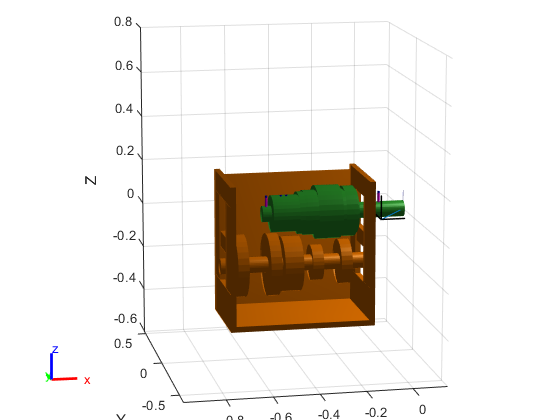


% addCollision(mainshaft.Base, ms2_cyl, axang2tform([0 1 0 pi/2]));

for i = 1:6
    addCollision(mainshaft.Bodies{i}, ms2_cyl, axang2tform([0 1 0 pi/2]));
end

addCollision(mainshaft.Bodies{7}, ms2_cyl, axang2tform([0 1 0 pi/2]));
addCollision(mainshaft.Bodies{8}, collisionCylinder(0.225/2,0.050), axang2tform([0 1 0 pi/2]));
addCollision(mainshaft.Bodies{9}, collisionCylinder(0.239/2,0.06), axang2tform([0 1 0 pi/2]));
addCollision(mainshaft.Bodies{10}, collisionCylinder(0.240/2, 0.05), axang2tform([0 1 0 pi/2]));
addCollision(mainshaft.Bodies{11}, collisionCylinder(0.190/2, 0.100), axang2tform([0 1 0 pi/2]));
addCollision(mainshaft.Bodies{12}, collisionCylinder(0.160/2,0.06), axang2tform([0 1 0 pi/2]));
addCollision(mainshaft.Bodies{13}, collisionCylinder(0.072/2,0.04), axang2tform([0 1 0 pi/2]));
addCollision(mainshaft.Bodies{14}, collisionCylinder(0.165/2,0.142), axang2tform([0 1 0 pi/2]));
addCollision(mainshaft.Bodies{15}, collisionCylinder(0.200/2,0.384-0.142), axang2tform([0 1 0 pi/2]));


% mainshaft.Bodies{1}
if show_model
    show(mainshaft, 'Collisions','on', 'Visuals',"off");
end


% xlim([-1.67 0.08])
% ylim([-1.00 0.76])
% zlim([-0.64 1.10])
% view([-0.72 18.21])

## Planning

% 
% config = homeConfiguration(mainshaft);
% [areIntersecting, dist, witnessPoints] = checkCollision(mainshaft, config, environment_collisions)

planning = false; 

if planning


    % for i = 1:length(environment_collisions)
    %     [areIntersecting, ~, ~] = checkCollision(mainshaft, homeConfiguration(mainshaft), environment_collisions, "IgnoreSelfCollision", "on");
    %     if areIntersecting
    %         environment_collisions{i}
    %     end
    % end
    % 
    
    
    
    
    environment_collisions = {front1, front2, front3, front4, front5, rear1, rear2, rear3, rear4, rear5, cs_1, cs_2, cs_3, cs_4, cs_5, cs_6};
    rrt = manipulatorRRT(mainshaft, environment_collisions)
    rrt.IgnoreSelfCollision = true;
    rrt.SkippedSelfCollisions = "adjacent";
    
    
    
    startConfig = homeConfiguration(mainshaft);
    goalConfig = [0 0 3 0 0 0];
    
    rng(5)
    path = plan(rrt, startConfig, goalConfig);
    
    
    interpPath = interpolate(rrt,path);
    clf
    for i = 1:20:size(interpPath,1)
        show(mainshaft,interpPath(i,:));
        hold on
    end
    
    save transmission_assignment.mat
    
    show(environment_collisions{1})
    show(environment_collisions{2})
    show(environment_collisions{3})
    show(environment_collisions{4})
    show(environment_collisions{5})
    show(environment_collisions{6})
    show(environment_collisions{7})
    show(environment_collisions{8})
    show(environment_collisions{9})
    show(environment_collisions{10})
    show(environment_collisions{11})
    show(environment_collisions{12})
    show(environment_collisions{13})
    hold off
end